clear all; clc;

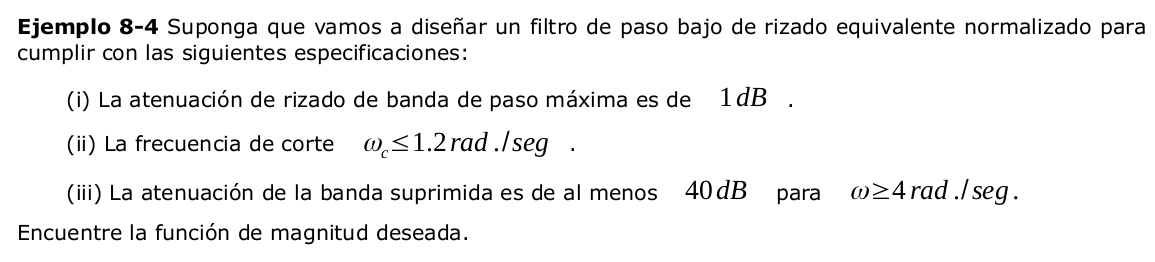


syms w 'real'
syms n k 'integer'

%% datos del problema 232
Rl=1;
Rs=1;
Ap=sym('1');        %banda de paso
wc=sym('1.2');
As=sym('40');       %banda suprimida
ws=sym('4'); % w>=4

%% cálcular la constante de ripple C(1)=1
%10*log10( H_j1) = 10* log10( 1 / (1+e^2) = -Ap ;
e=sqrt( 10^(Ap/10)-1 )

$$e = 0.5088$$


%% calcular el orden en la banda suprimida
%H2(jw)=1 /(1+( e * Cn(w))^2 )
%Cn(w)=cos (n*acos(w)); en la banda de paso
%Cn(w)=cosh (n*acosh(w)); en la banda suprimida
n1= acosh(( sqrt( 10^(3/10) -1 ))/e)/ (acosh(wc))

$$n1 = 2.0790$$

n1=ceil(n1)

$$n1 = 3$$

n2= acosh(( sqrt(10^(As/10) -1 ))/e)/ (acosh(ws));
n2=ceil(n2)

$$n2 = 3$$

n=max(n1,n2)

$$n = 3$$



%calcular los polos y ceros
%bk(k)=(asinh( ((-1)^k)/e ) )/n
bk(k)=(asinh( 1/e ) )/n

$$bk(k) = 0.4760$$


theta(k)= (2*k-1)/(2*n)*pi ;
sk(k)=+sinh( bk(k) )*sin(theta(k)) +j*cosh( bk(k) )*cos(theta(k)) 

$$sk(k) = 0.4942\,\sin\left(1.0472\,k-0.5236\right)+1.1154\,\cos\left(1.0472\,k-0.5236\right)\,\mathrm{i}$$

r=[];
for m=1:2*n
    r(m)=sk(m);
end
syms s;

H2(s)=1/collect( prod(s-r) )

$$H2(s) = \frac{1}{s^{6}+1.5000\,s^{4}+0.5625\,s^{2}-0.2414}$$

[b, a]=numden(H2(s));
B=sym2poly(collect(b));
A=sym2poly(collect(a));
A=A/B(1); B=B/B(1)/abs(A(end));A=A/abs(A(end));
H2(s)=poly2sym(B)/poly2sym(A)

$$H2(s) = \frac{4.1422}{4.1422\,x^{6}+6.2132\,x^{4}+2.3299\,x^{2}-1}$$

collect(H2(j*w))

$$ans = \frac{7.0369e+19}{7.0369e+19\,x^{6}+1.0555e+20\,x^{4}+3.9581e+19\,x^{2}-1.6988e+19}$$

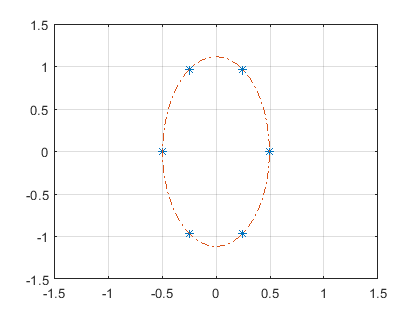

plot(real(r), imag(r),'*'), hold on, ...

plot( sinh( bk([0:0.1:2*pi]) ).*sin([0:0.1:2*pi])+ j*cosh( bk([0:0.1:2*pi]) ).*cos([0:0.1:2*pi]),'-.' ),...
hold off; xlim([-1.5,1.5]), grid on;

